# Split training set and shuffle 

Three sets: the training set (70%) for hyperparameter search, an extra training set(10%), and a test set (20%). The idea here is to combine the training set and an extra training set (70%+10%) and then randomly sample out of it (70%) to train the model with the known hyperparameters and test such model on the test set (20%). Repeat this testing procedure 10 times and compute the mean and standard deviations of the overall accuracy as well as per class accuracies.

## Load data

fs = 512;
% Downsample by a factor dsFactor
dsFactor = 4;

% read lables
ds = load('raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;

% read filtered EEG data
currentDir = dir;
currentDir(1:2) = [];
for i = 1:numel(currentDir)
    if strcmp(currentDir(i).name,'RawData')
        %disp('get RawData')
        pathToEEG = fullfile(currentDir(i).folder,currentDir(i).name);
        break
    end
end
eegFiles = dir(pathToEEG);
eegFiles(1:2) = [];
Ds = {};

frontElectrodesLabels = ["Fp1", "Fp2", "Fz", "AF3", "AF4", "F7", "F8"]; % 
allElectrodesLables =[];
categroies = {'blink', 'n/a', 'muscle-artifact'};
for k = 1:31
    tokens = strsplit(ds.Row{k}, '\');
    fileName = tokens{end};
    eegTable = readtable([pathToEEG,'\',eegFiles(k).name]);
    filteredSignals = passbandBlinks(eegTable(:, contains(eegTable.Properties.VariableNames, frontElectrodesLabels)), fs);
    
    filteredSignals = array2table(resample(filteredSignals.Variables, 1, dsFactor),  'VariableNames', filteredSignals.Properties.VariableNames);
    roi = ds(k,:).detect_blinks{1};
    roi(:, 1).Variables = ceil(roi(:, 1).Variables/dsFactor);
    masked = getmask({filteredSignals, roi});
    
    Ds{k} = masked; 
    Ds{k}{2} = categorical(Ds{k}{2},categroies);
end

## Visualise labeled data

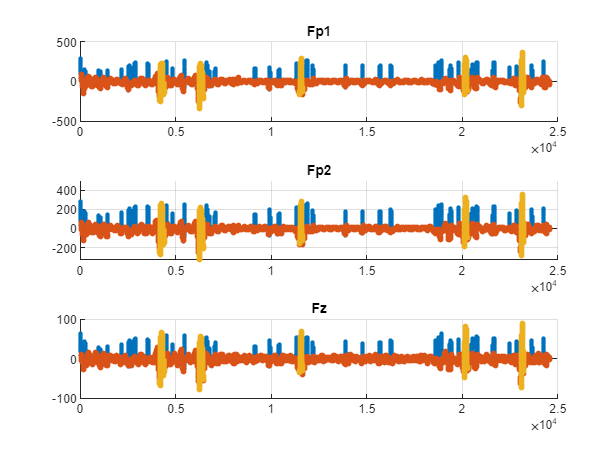

ind = 1;
figure('color', 'white'), 
for k = 1:width(Ds{ind}{1})
    subplot(length(frontElectrodesLabels),1,k), hold on,  grid on, title(frontElectrodesLabels(k));
    %plot(1:height(Ds{ind}{1}), Ds{ind}{1}(:,k).Variables, LineWidth=2);
    stem(find(Ds{ind}{2} == "blink"),           Ds{ind}{1}(Ds{ind}{2} == "blink", k).Variables,             LineWidth=2, MarkerSize=1);
    stem(find(Ds{ind}{2} == "n/a"),             Ds{ind}{1}(Ds{ind}{2} == "n/a", k).Variables,               LineWidth=3, Color=[0.8500    0.3250    0.0980], MarkerSize=1);
    stem(find(Ds{ind}{2} == "muscle-artifact"), Ds{ind}{1}(Ds{ind}{2} == "muscle-artifact", k).Variables,   LineWidth=3, Color=[0.9290    0.6940    0.1250], MarkerSize=1);
end

## None overlapping data splition

slice = 512;
rng(1);

ratioValidationTest = 0.2;
ratioPreserveTrain = 0.1;
ratioSearchTrain = (1-ratioValidationTest-ratioPreserveTrain)*0.8;
ratioSearchTest = (1-ratioValidationTest-ratioPreserveTrain)*(1-0.8);
ratioTestSave = ratioPreserveTrain+ratioSearchTest;
ratios = [ratioSearchTrain,ratioTestSave,ratioValidationTest];

XSearchTrain = {};
YSearchTrain = {};
XTestSave = {};
YTestSave = {};
XValidationTest = {};
YValidationTest = {};


for k = 1:length(Ds)
    [indexSearchTrain,indexTestSave,indexValidationTest] = splitSignalIntoSeveralSegments(Ds{k}{1}, ratios, slice/8, slice);

    for l = 1:size(indexSearchTrain, 1)
        XSearchTrain{end+1} = Ds{k}{1}(indexSearchTrain(l,:), :).Variables';
        YSearchTrain{end+1} = Ds{k}{2}(indexSearchTrain(l,:))';
    end
    for l = 1:size(indexTestSave, 1)
        XTestSave{end+1} = Ds{k}{1}(indexTestSave(l,:), :).Variables';
        YTestSave{end+1} = Ds{k}{2}(indexTestSave(l,:))';
    end
    for l = 1:size(indexValidationTest, 1)
        XValidationTest{end+1} = Ds{k}{1}(indexValidationTest(l,:), :).Variables';
        YValidationTest{end+1} = Ds{k}{2}(indexValidationTest(l,:))';
    end 
end

#### Creat dir and store sequence data also wavelet transformed data

% currentDir = dir;
% currentDir(1:2) = [];

numTesting = 30;

% 'Img' is the place that store imgs for pixelclsificatin
% % orthers are store as .mat
% tDir = fullfile('DataSet','HyperparameterSearch','Train','Img');mkdir(tDir);
% tDir = fullfile('DataSet','HyperparameterSearch','Test','Img');mkdir(tDir);
% for i = 1:numTesting
%     tDir = fullfile('DataSet','Test','Train',['Img',num2str(i)]);mkdir(tDir);    
% end
% tDir = fullfile('DataSet','Test','Test','Img');mkdir(tDir);
% tDir = fullfile('DataSet','PreservedTrain','Img');mkdir(tDir); % noneed

save(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat'),"XSearchTrain","-mat");
save(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat'),"YSearchTrain","-mat");
% creatWaveletTransformedImg(XSearchTrain,fullfile('DataSet','HyperparameterSearch','Train','Img'));
% creatCategorizedImg(YSearchTrain,fullfile('DataSet','HyperparameterSearch','Train','Img'));
% %---
save(fullfile('DataSet','Test','Test','XValidationTest.mat'),"XValidationTest","-mat");
save(fullfile('DataSet','Test','Test','YValidationTest.mat'),"YValidationTest","-mat");
% creatWaveletTransformedImg(XValidationTest,fullfile('DataSet','Test','Test','Img'));
% creatCategorizedImg(YValidationTest,fullfile('DataSet','Test','Test','Img'));

[searchTestIndex,preserveTrainIndex,~]=dividerand(numel(XTestSave),ratioSearchTest/ratioTestSave,ratioPreserveTrain/ratioTestSave,0);

XSearchTest = XTestSave(searchTestIndex);
YSearchTest = YTestSave(searchTestIndex);
XPreserveTrain = XTestSave(preserveTrainIndex);
YPreserveTrain = YTestSave(preserveTrainIndex);

save(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat'),"XSearchTest","-mat");
save(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat'),"YSearchTest","-mat");
% creatWaveletTransformedImg(XSearchTest,fullfile('DataSet','HyperparameterSearch','Test','Img'));
% creatCategorizedImg(YSearchTest,fullfile('DataSet','HyperparameterSearch','Test','Img'));
%---
save(fullfile('DataSet','PreservedTrain','XPreserveTrain.mat'),"XPreserveTrain","-mat");
save(fullfile('DataSet','PreservedTrain','YPreserveTrain.mat'),"YPreserveTrain","-mat");
% creatWaveletTransformedImg(XPreserveTrain,fullfile('DataSet','PreservedTrain','Img'));
% creatCategorizedImg(YPreserveTrain,fullfile('DataSet','PreservedTrain','Img'));


% combine the training set and an extra training set (70%+10%) and then 
% randomly sample out of it (70%) 10 times 
XTestTrainBase = [XSearchTrain,XTestSave];
YTestTrainBase = [YSearchTrain,YTestSave];
for i=1:numTesting
    rng(i);
    [testTrainIndex,addTestTestIndex,~]=dividerand(numel(XTestTrainBase),0.8,0.2,0);
    % maybe add a check here to make sure preserved set shuffle into TestTrain
    XTestTrain = XTestTrainBase(testTrainIndex);
    YTestTrain = YTestTrainBase(testTrainIndex);
    XTestTest = [XTestTrainBase(addTestTestIndex),XValidationTest];
    YTestTest = [YTestTrainBase(addTestTestIndex),YValidationTest];
    save(fullfile('DataSet','Test','Test',['XTestTest',num2str(i),'.mat']),"XTestTest","-mat");
    save(fullfile('DataSet','Test','Test',['YTestTest',num2str(i),'.mat']),"YTestTest","-mat");    
    save(fullfile('DataSet','Test','Train',['XTestTrain',num2str(i),'.mat']),"XTestTrain","-mat");
    save(fullfile('DataSet','Test','Train',['YTestTrain',num2str(i),'.mat']),"YTestTrain","-mat");
    % creatWaveletTransformedImg(XTestTrain,fullfile('DataSet','Test','Train',['Img',num2str(i)]));
    % creatCategorizedImg(YTestTrain,fullfile('DataSet','Test','Train',['Img',num2str(i)]));
    % creatWaveletTransformedImg(XTestTest,fullfile('DataSet','Test','Test',['Img',num2str(i)]));
    % creatCategorizedImg(YTestTest,fullfile('DataSet','Test','Test',['Img',num2str(i)]));
end
rng(1)

### Image sequence

% imdsTrain = imageDatastore(fullfile('DataSet','HyperparameterSearch','Train','Img','WTImg'),FileExtensions=".jpg");
% imdsTest = imageDatastore(fullfile('DataSet','HyperparameterSearch','Test','Img','WTImg'),FileExtensions=".jpg");

imgSize = size(imread(imdsTrain.Files{1,1}));
sequenceSize = [imgSize(1) imgSize(3) imgSize(2) 1];
sequenceTrain = ones(sequenceSize);
cellTrain = {};
for i =1:numel(imdsTrain.Files)
    img = imread(imdsTrain.Files{i,1});
    sequenceShape = [size(img,1) size(img,3) 1];
    timePiece = ones(sequenceShape);
    for j = 1:size(img,2)
        timePiece = cat(3,timePiece,reshape(img(:,j,:),sequenceShape));
    end
    timePiece = timePiece(:,:,2:end);
    sequenceTrain = cat(4,sequenceTrain,timePiece);
    cellTrain{end+1} = timePiece;
end
XTrain=sequenceTrain(:,:,:,2:end);

sequenceTest = ones(sequenceSize);
cellTest={};
for i =1:numel(imdsTest.Files)
    img = imread(imdsTest.Files{i,1});
    sequenceShape = [size(img,1) size(img,3) 1];
    timePiece = ones(sequenceShape);
    for j = 1:size(img,2)
        timePiece = cat(3,timePiece,reshape(img(:,j,:),sequenceShape));
    end
    timePiece = timePiece(:,:,2:end);
    sequenceTest = cat(4,sequenceTest,timePiece);
    cellTest{end+1} = timePiece;
end
XTest=sequenceTest(:,:,:,2:end);

% save(fullfile('DataSet','HyperparameterSearch','Train','imgSeqTrain.mat'), 'XTrain', '-v7.3');
% save(fullfile('DataSet','HyperparameterSearch','Test','imgSeqText.mat'), 'XTest', '-v7.3');
save(fullfile('DataSet','HyperparameterSearch','Train','imgSeqCellTrain.mat'), 'cellTrain', '-v7.3');
save(fullfile('DataSet','HyperparameterSearch','Test','imgSeqCellText.mat'), 'cellTest', '-v7.3');